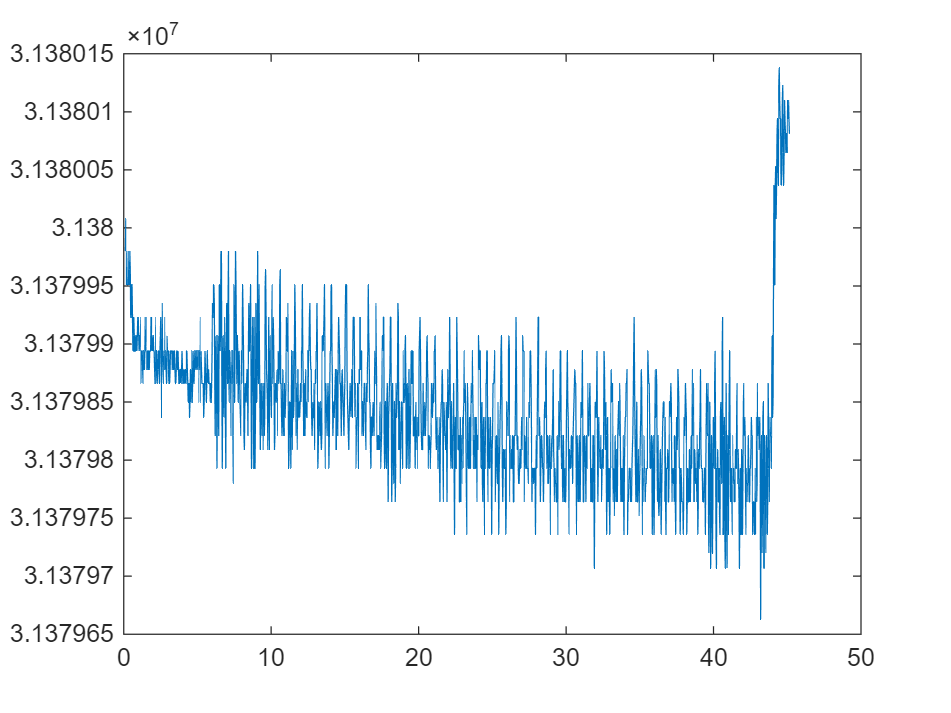

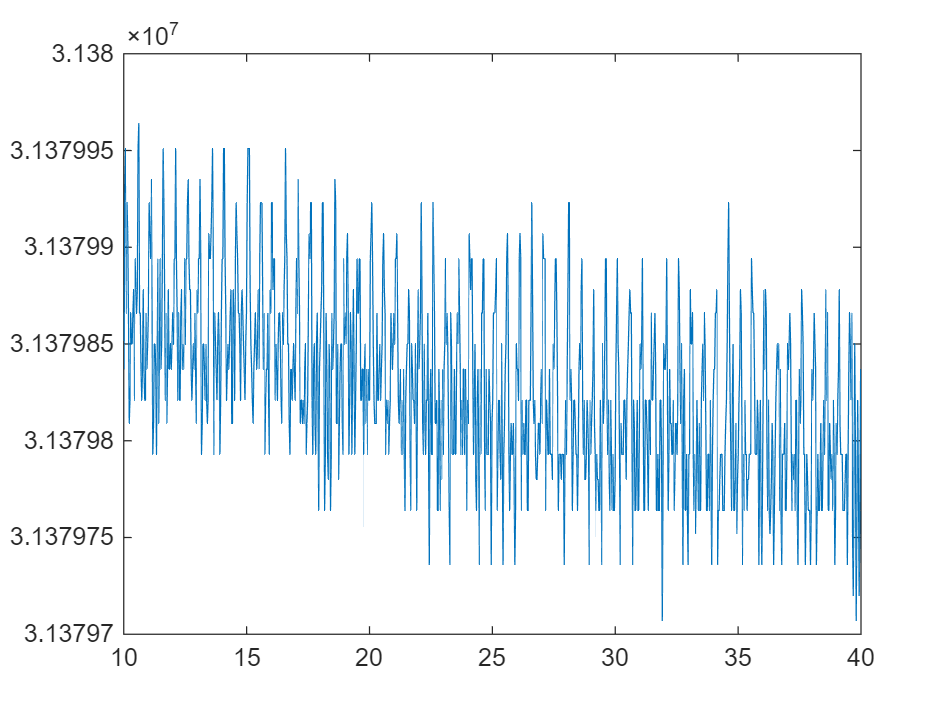

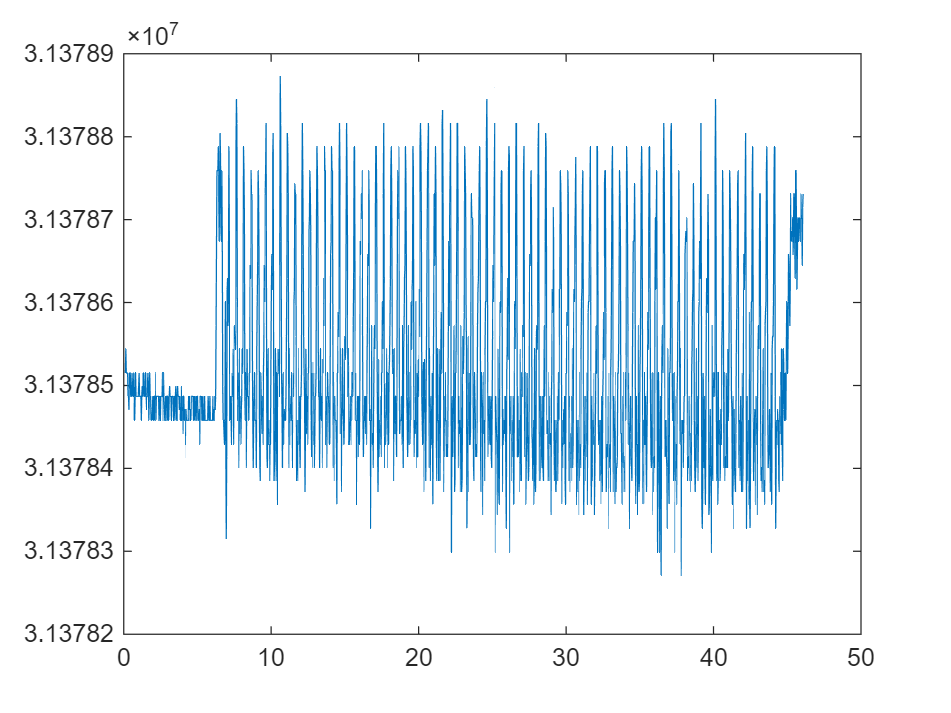

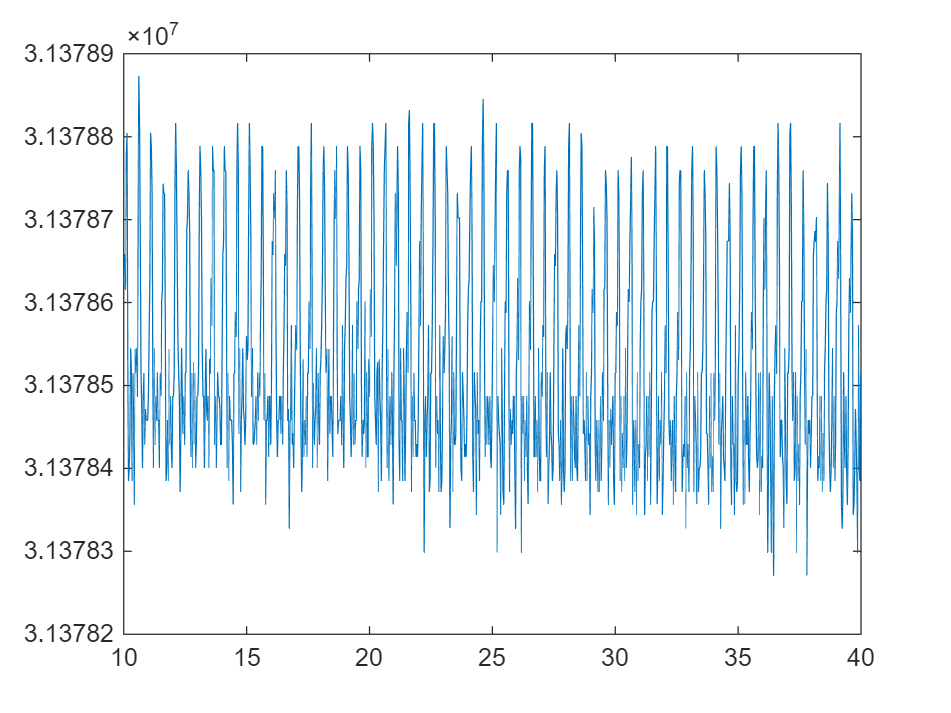

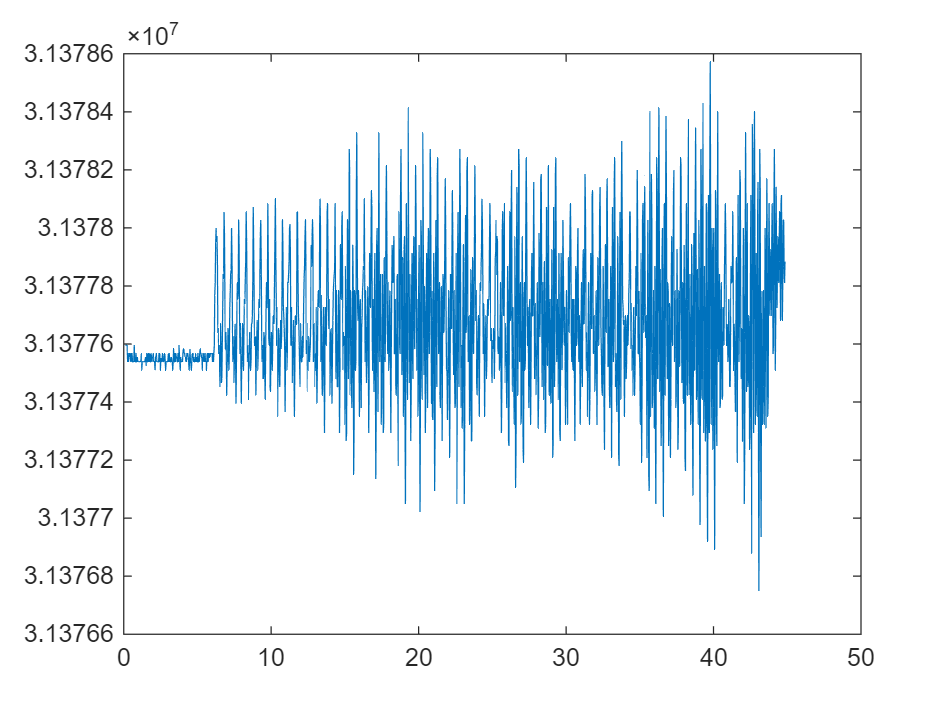

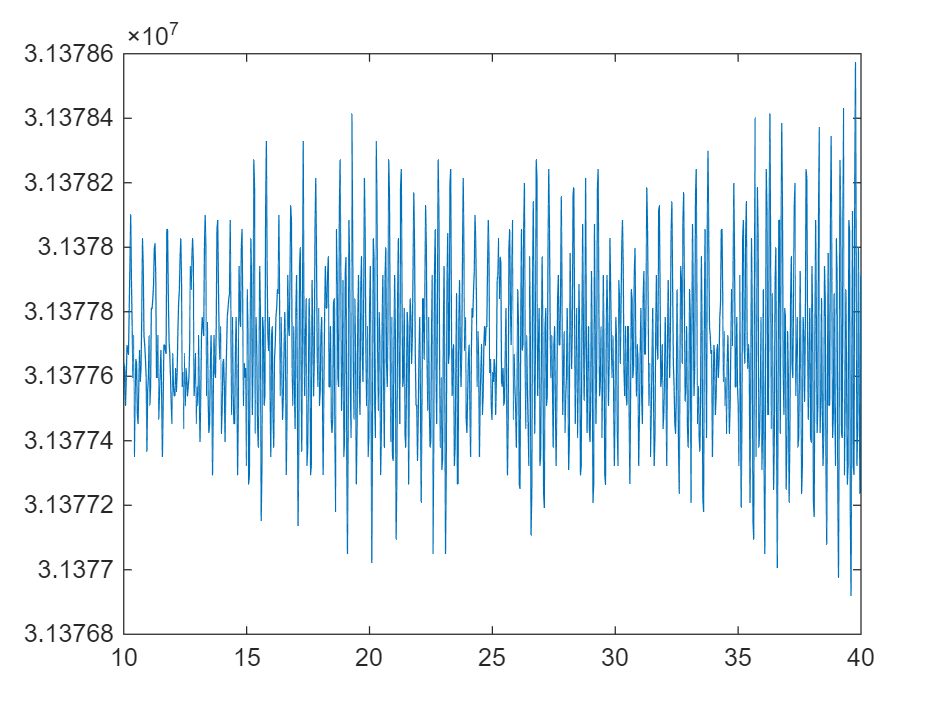

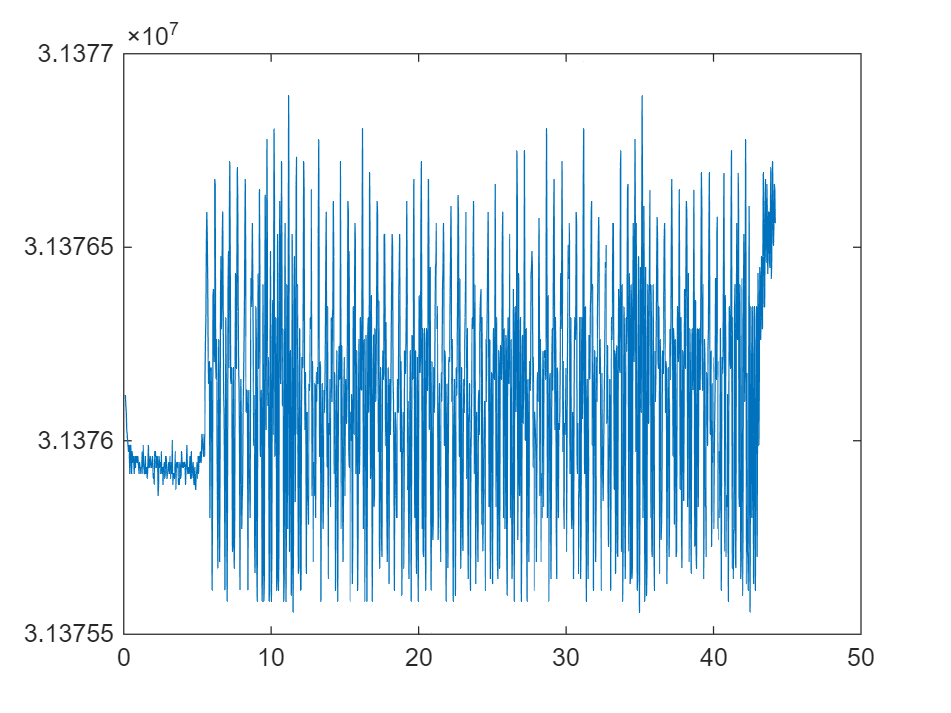

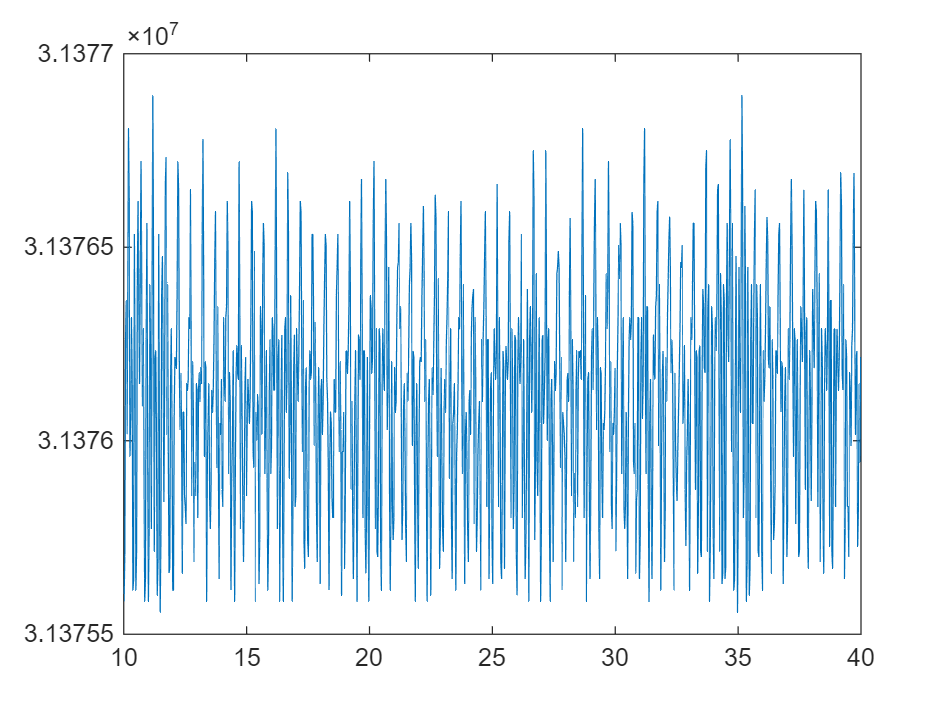

weeks = [20, 26, 30, 34, 40];

volume = [4, 10, 16, 27, 40];
delta_v = [0.5, 2, 3, 4, 10];

data2plot = [];

data2compare = cell(1,length(weeks));

p2pdata = cell(length(weeks),1);

for i = 1:length(weeks)

    filename = strcat('week_',num2str(weeks(i)),'.csv');

    raw_data = readtable(filename,'Delimiter',',');

    % Take care of header chunk
    raw_time = raw_data{:,1};
    [row, ~] = find(isnan(raw_time));

    if ~isempty(row)
        % double check to make sure nan is from the header instead of data
        if (row(end) - row(1) + 1) == length(row)

            raw_data = raw_data(row(end)+1:end,:); % clip header
        end
    end
    raw_data(end,:) = [];   % get rid of last line in case of incomplete data log

    % Raw time & data
    time = raw_data{:,1}./1000; % in seconds
    data = raw_data{:,2};

    figure;
    plot(time,data);

    pump_idx = (time >= 10) & (time <= 40);

    time_pump = time(pump_idx);
    data_pump = data(pump_idx);

    figure;
    plot(time_pump,data_pump);

    ts = 0.03;
    fs = 1/ts;

    rs_time = 1:ts:350;

    [~,end_idx] = min(abs(rs_time - time_pump(end)));
    [~,stt_idx] = min(abs(rs_time - time_pump(1)));


    rs_time  = rs_time(stt_idx:end_idx);
    rs_data = interp1(time,data,rs_time);


    % High pass to try to remove baseline

    cutoff_freq = 0.3;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
    hp_data= filtfilt(b, a, rs_data);

    figure;
    plot(rs_time,hp_data)

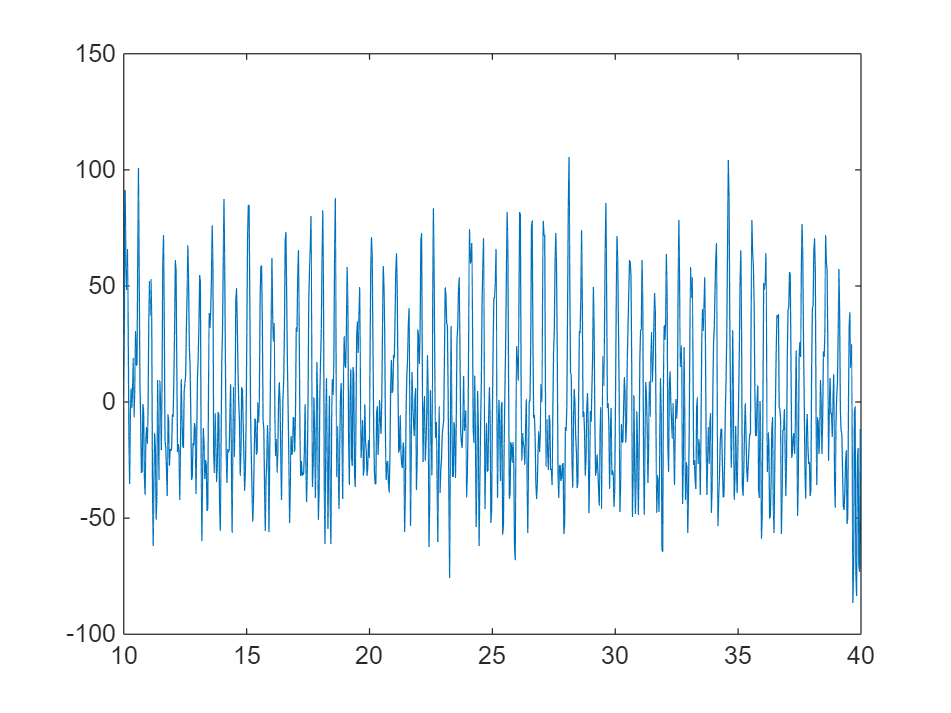

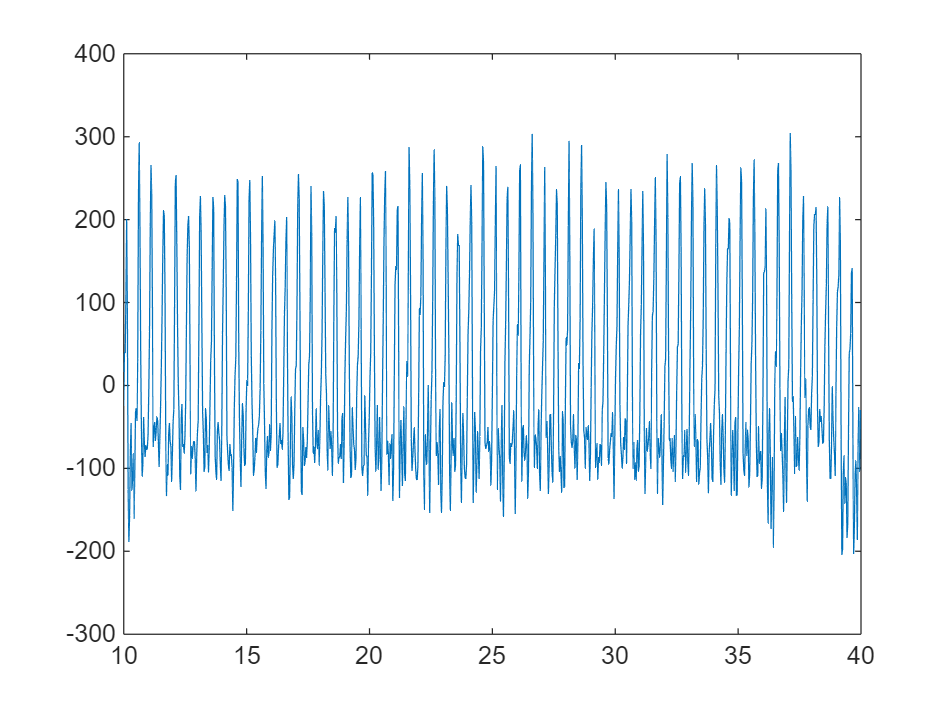

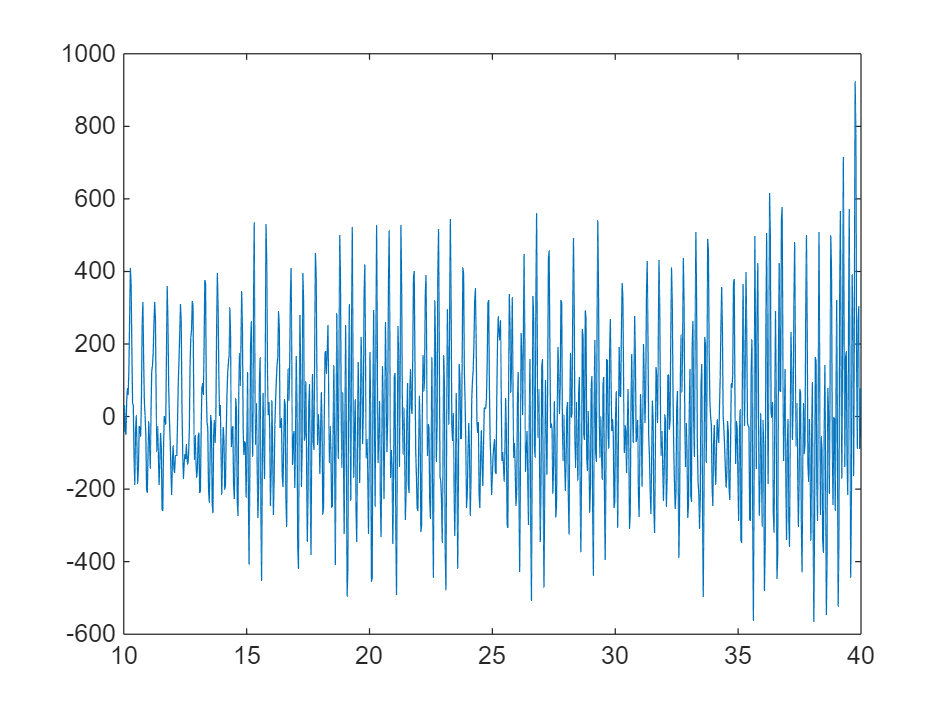

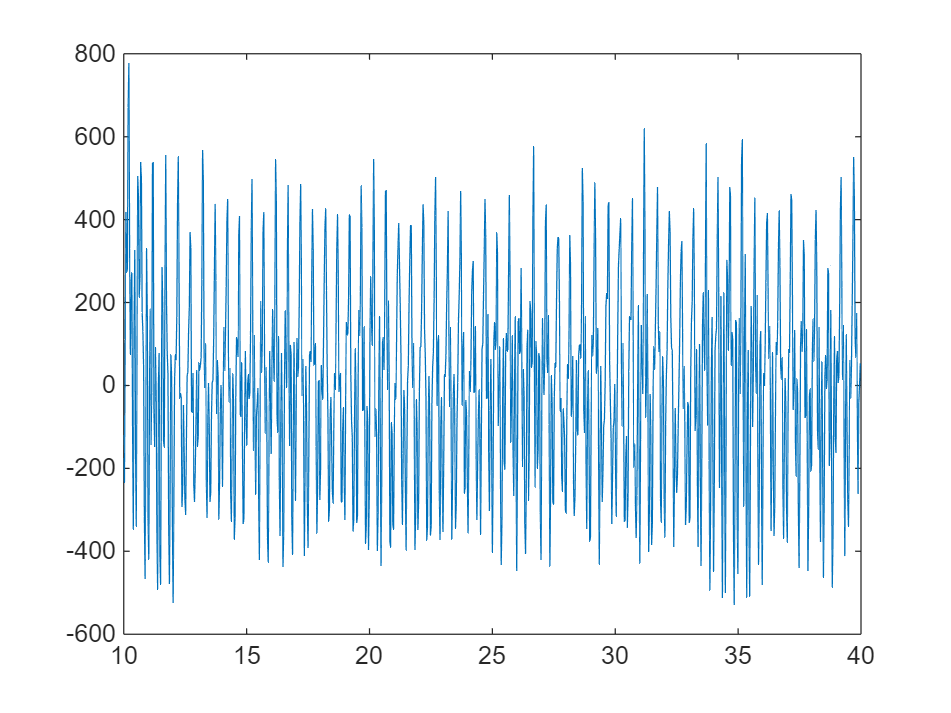

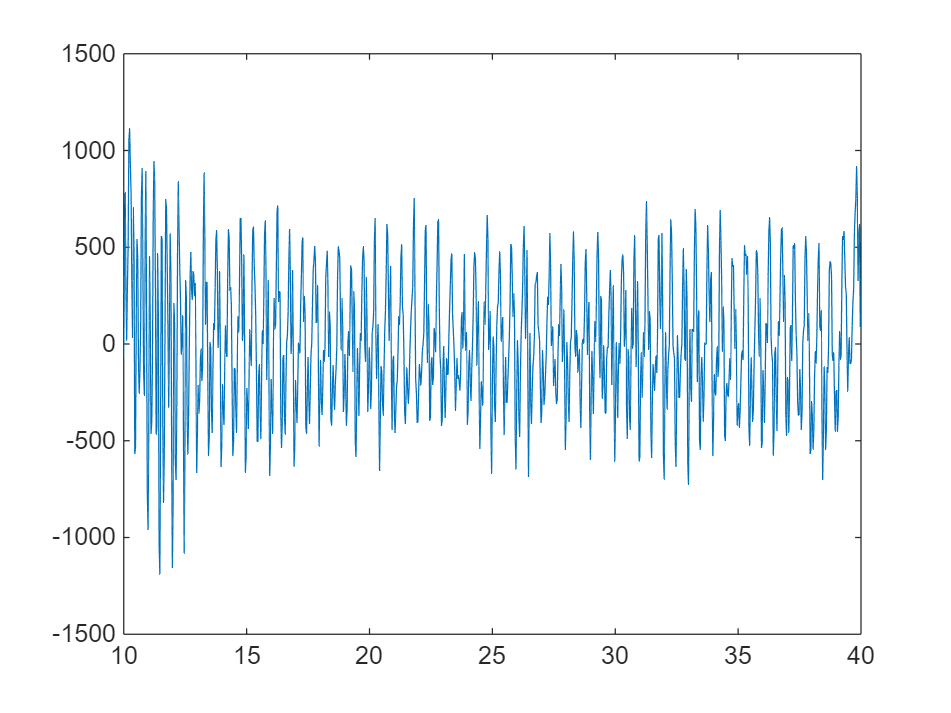

    % Low pass to try to remove noise

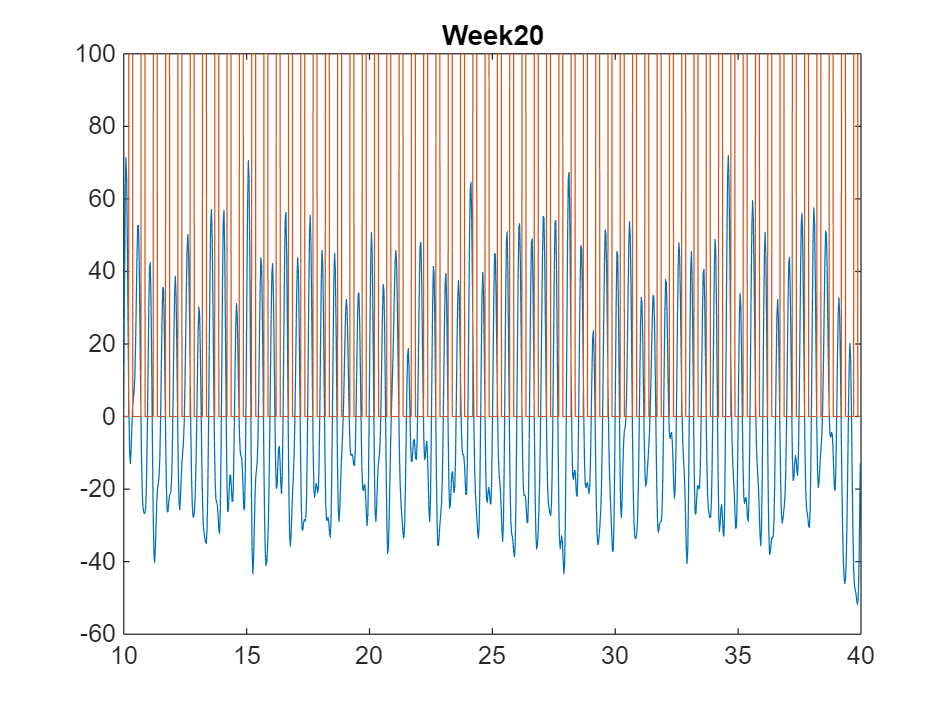

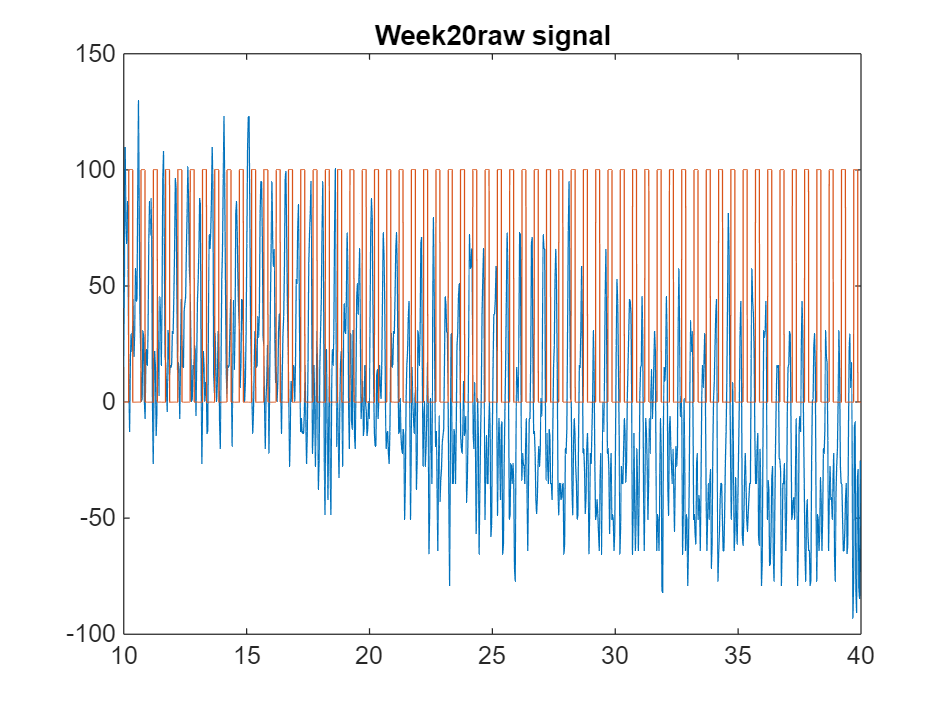

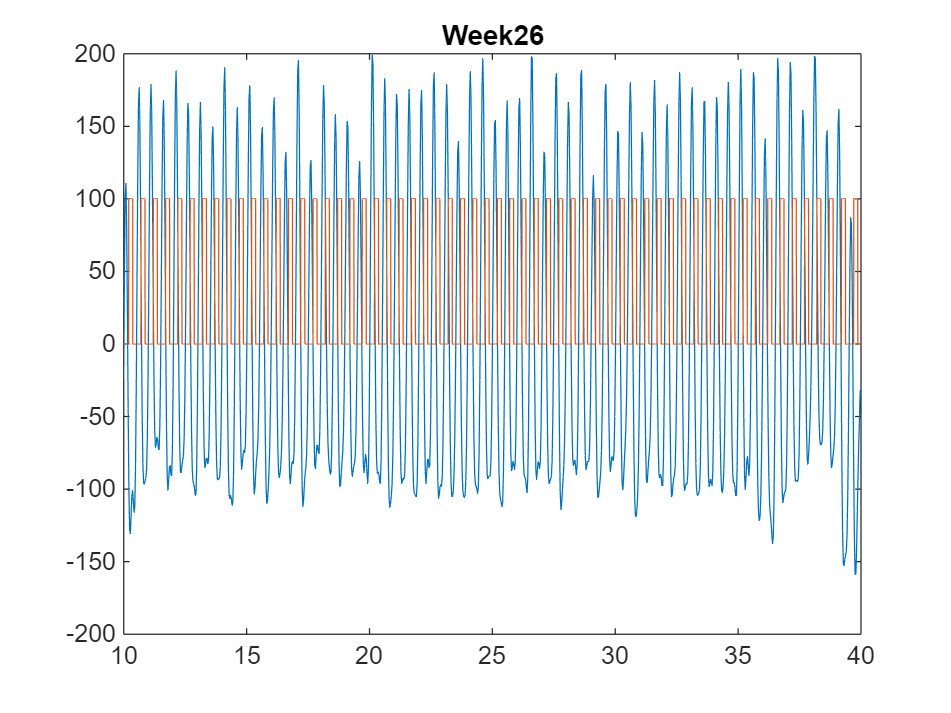

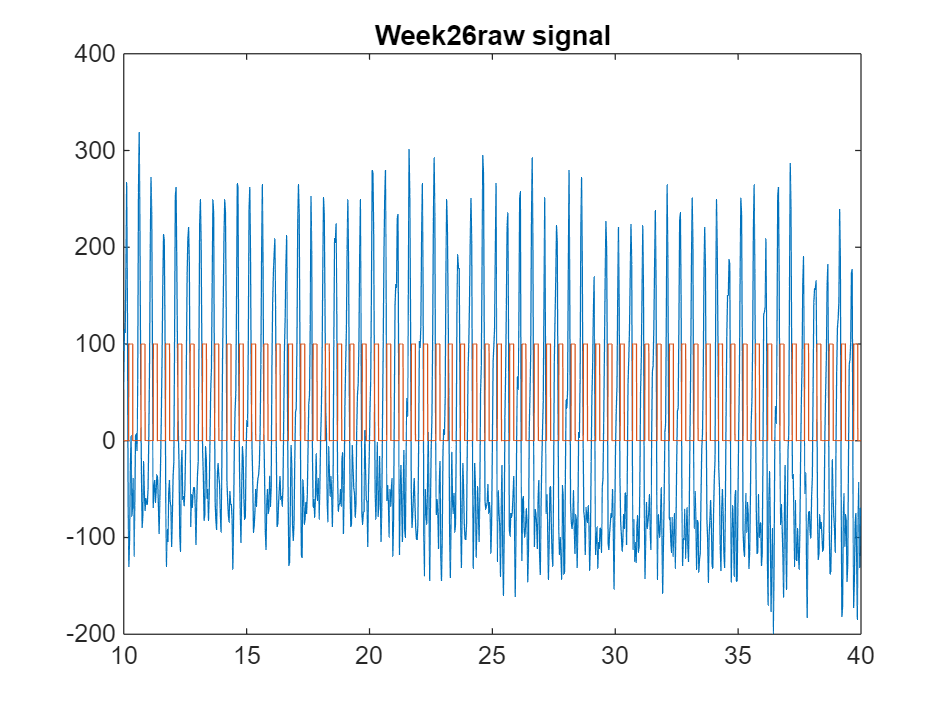

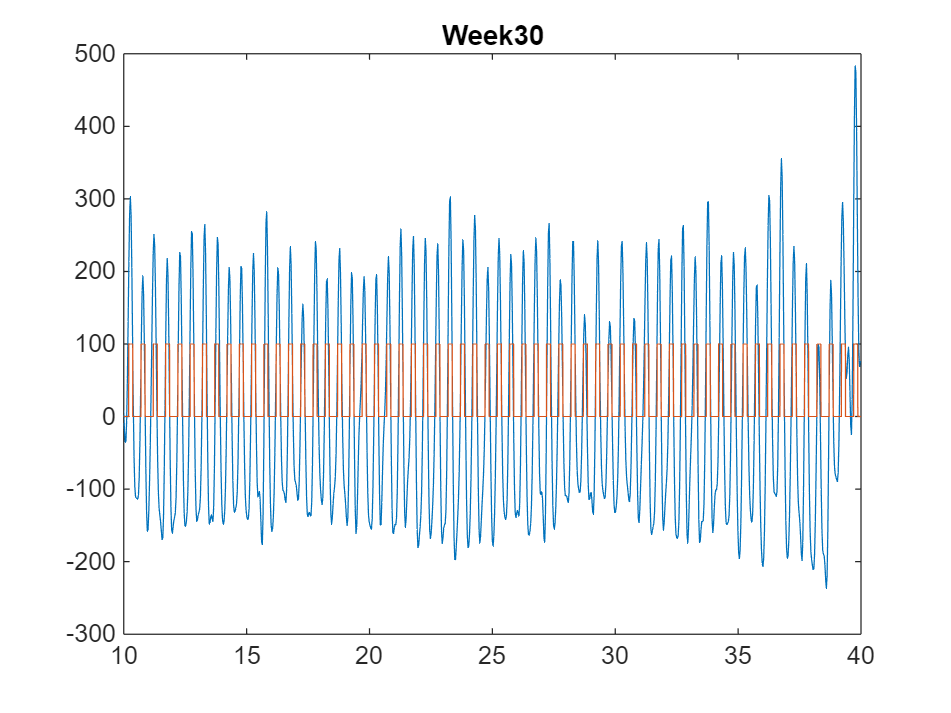

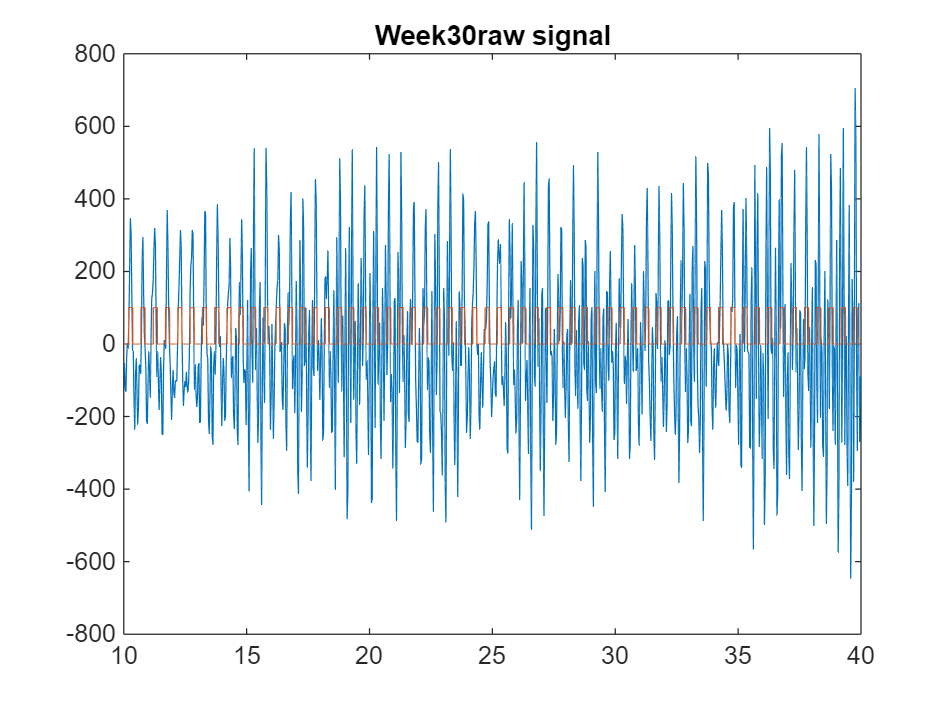

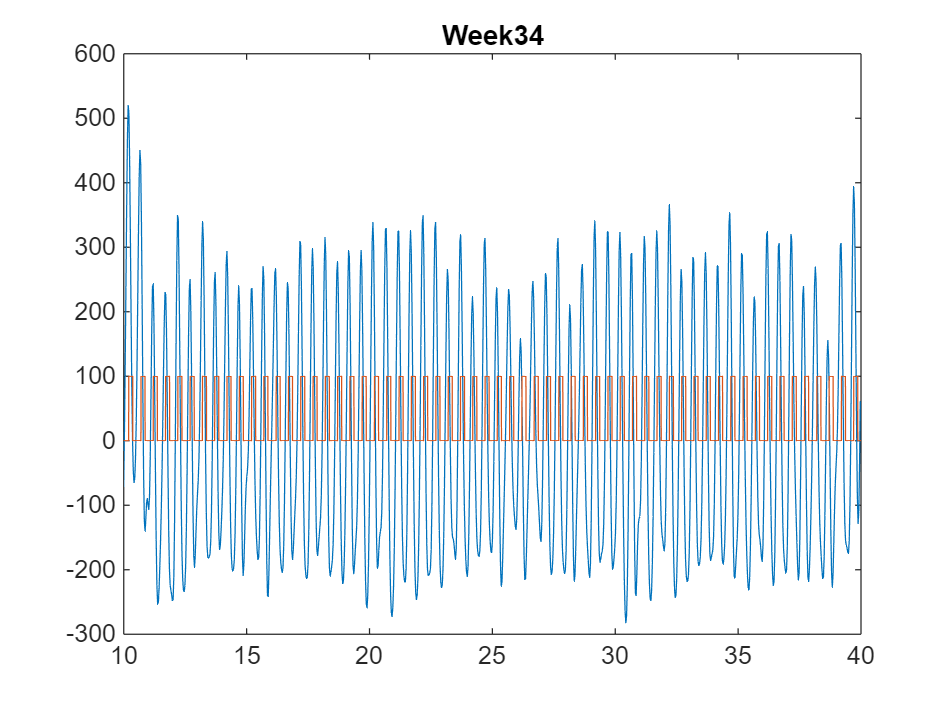

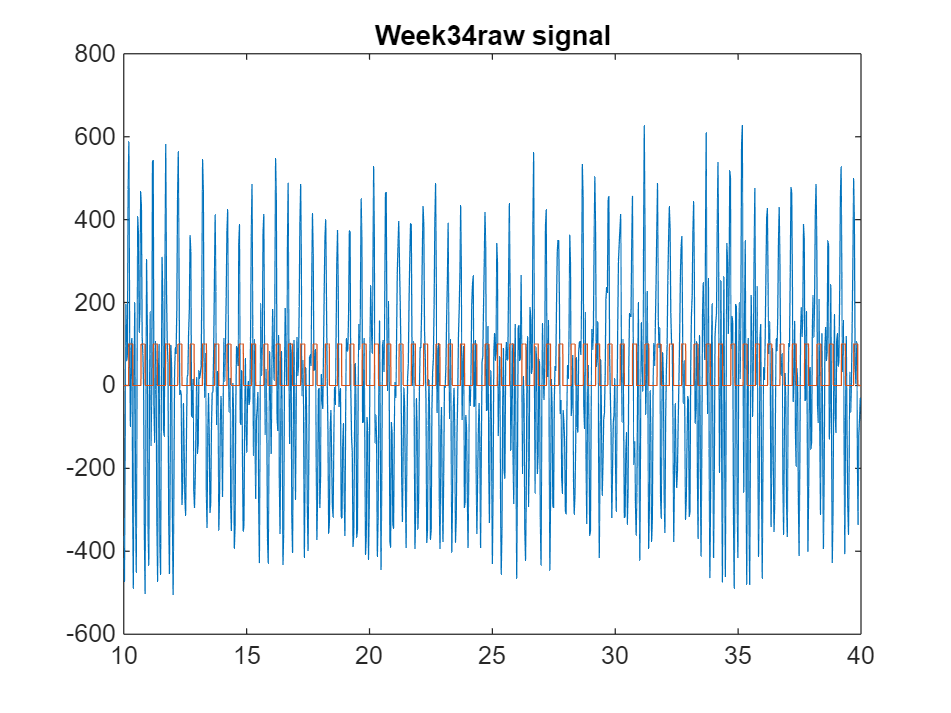


    cutoff_freq = 4;    % Cutoff frequency in Hz
    filter_order = 5;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
    bp_data= filtfilt(b, a, hp_data);

    act_time = 8:0.005:42;
    act_time(end) = [];
    act_time = act_time-0.13;
    single_act_data = [zeros(1,67),ones(1,33)]*100;
    act_data = repmat(single_act_data,1,68);

    figure;
    plot(rs_time,bp_data)
    hold on
    plot(act_time,act_data)
    hold off
    xlim([10 40])
    title_txt = strcat('Week ',num2str(weeks(i)));
    title(title_txt)

    figure;
    plot(rs_time,rs_data-mean(rs_data))
    hold on
    plot(act_time,act_data)
    hold off
    xlim([10 40])
    title_txt = strcat('Week ',num2str(weeks(i)),'raw signal');
    title(title_txt)

    clip_data = bp_data(rs_time>20&rs_time<30);
    clip_time = rs_time(rs_time>20&rs_time<30);


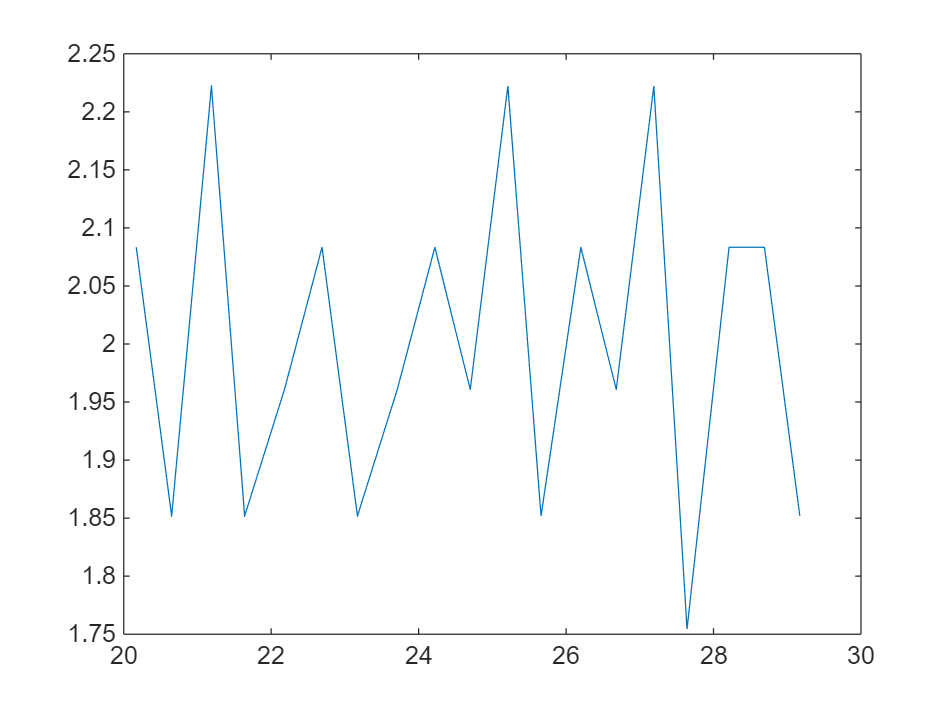

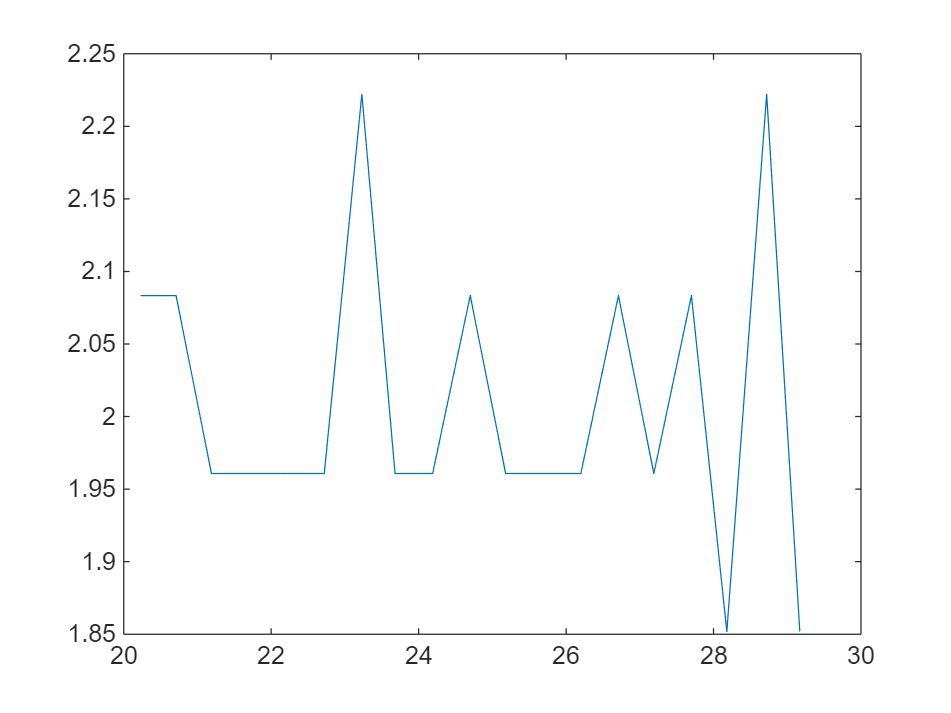

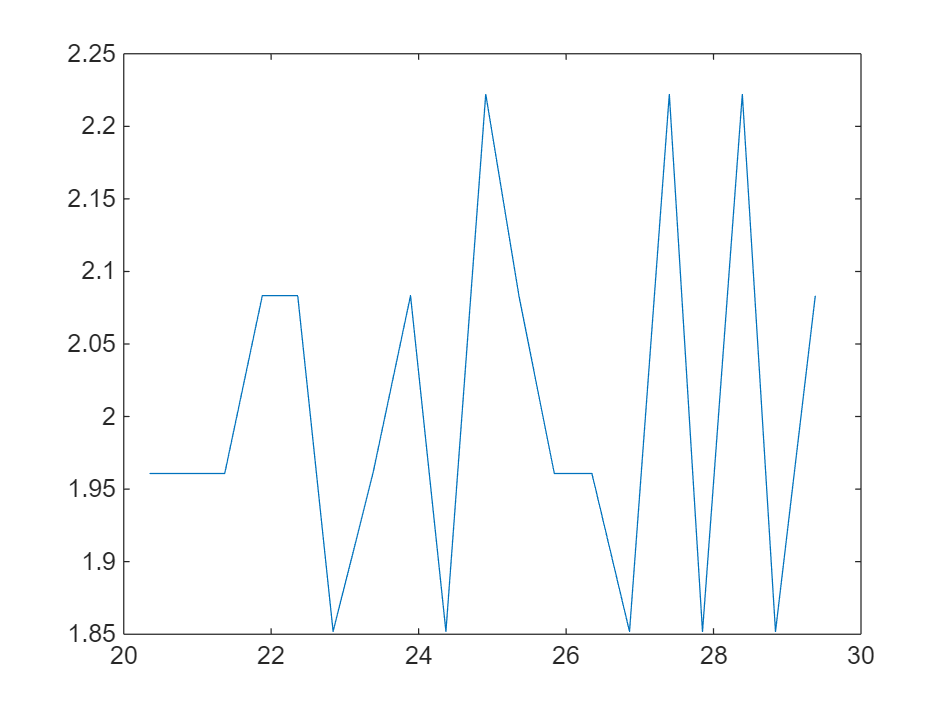

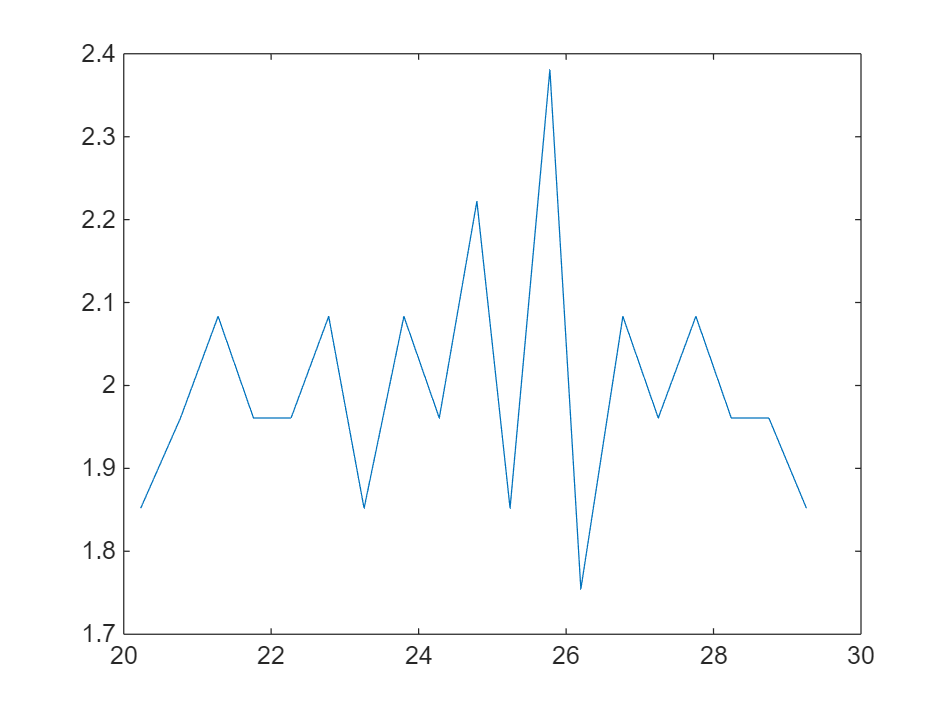

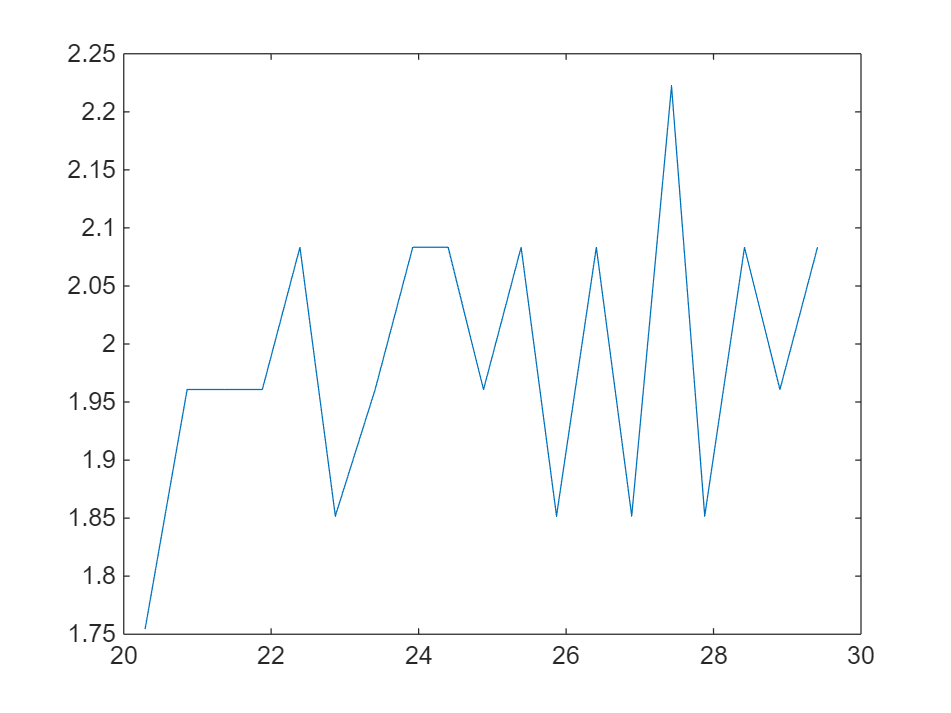

    % Frequency calculation
    cross_idx = find(clip_data(1:end-1).*clip_data(2:end) < 0 );
    time_cross = clip_time(cross_idx);
    data_cross = clip_data(cross_idx);
    pos_cross_idx = find(data_cross > 0);
    pos_time_cross = time_cross(pos_cross_idx);
    cross_time_diff = pos_time_cross(2:end) - pos_time_cross(1:end-1);
    cross_freq = 1./ cross_time_diff;
    figure;
    plot(pos_time_cross(1:end-1),cross_freq)


    % magnitude
    RMS = sqrt(mean(clip_data.^2))

    % p2p
    [pk_vals, pk_locs] = findpeaks(clip_data, clip_time,'MinPeakHeight', 10);
    [tr_vals_neg, tr_locs] = findpeaks(-clip_data, clip_time,'MinPeakHeight', 10);
    tr_vals = -tr_vals_neg;

    if tr_locs(1) < pk_locs(1)
        tr_locs(1) = []; tr_vals(1) = [];
    end

    N = min(numel(pk_locs), numel(tr_locs));
    pk_locs = pk_locs(1:N);
    pk_vals = pk_vals(1:N);
    tr_locs = tr_locs(1:N);
    tr_vals = tr_vals(1:N);

    p2p = pk_vals - tr_vals;
    mean_p2p = mean(p2p)
    std_p2p = std(p2p)

    wk_label = ones(length(p2p),1) .* weeks(i);
    vini_label = ones(length(p2p),1) .* volume(i);
    vdelta_label = ones(length(p2p),1) .* delta_v(i);
    


    p2pdata{i} = [wk_label,vini_label,vdelta_label, p2p'];

    data2save = [weeks(i),volume(i),delta_v(i),RMS,mean_p2p,std_p2p];
    data2plot = [data2plot;data2save];
    data2compare{i} = p2p;

end

RMS = 27.6866

mean_p2p = 72.8559

std_p2p = 14.8002

RMS = 99.6517

mean_p2p = 270.1031

std_p2p = 23.0670

RMS = 138.6895

mean_p2p = 384.9735

std_p2p = 58.9019

RMS = 178.0224

mean_p2p = 490.7338

std_p2p = 68.5271

RMS = 239.5830

mean_p2p = 660.3819

std_p2p = 110.3603

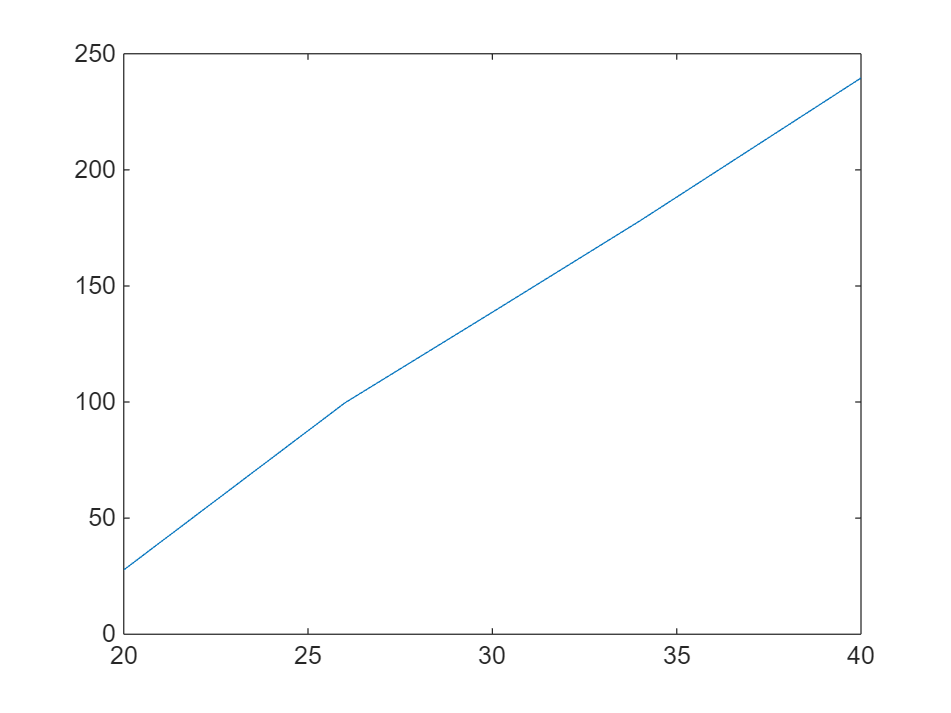

figure;
plot(data2plot(:,1),data2plot(:,4))

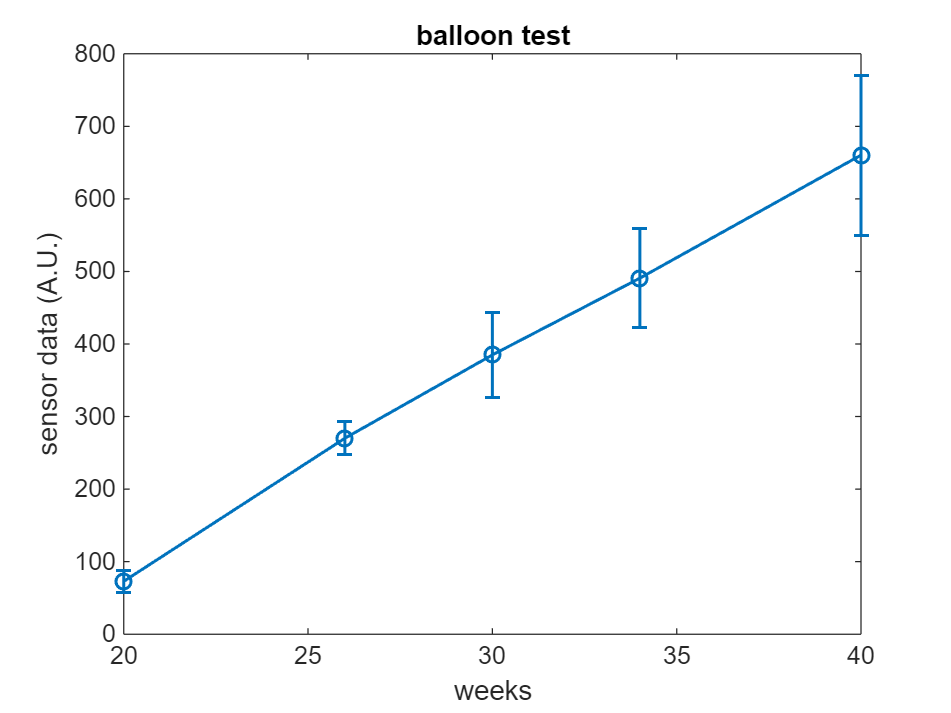


figure;
errorbar(data2plot(:,1),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('weeks')
ylabel('sensor data (A.U.)')
title('balloon test')

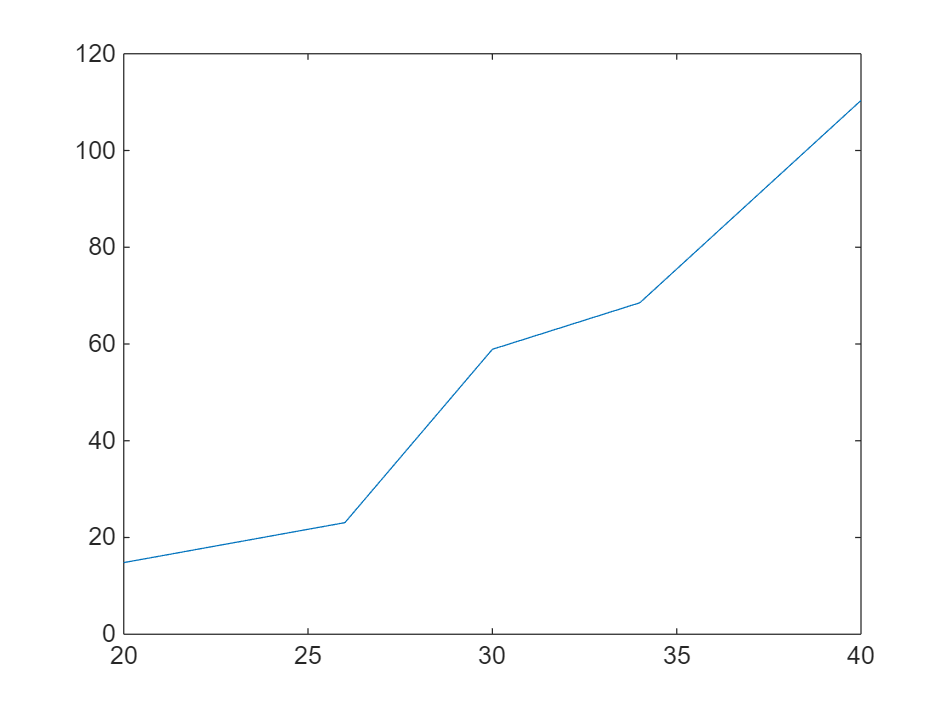



figure;
plot(data2plot(:,1),data2plot(:,6))

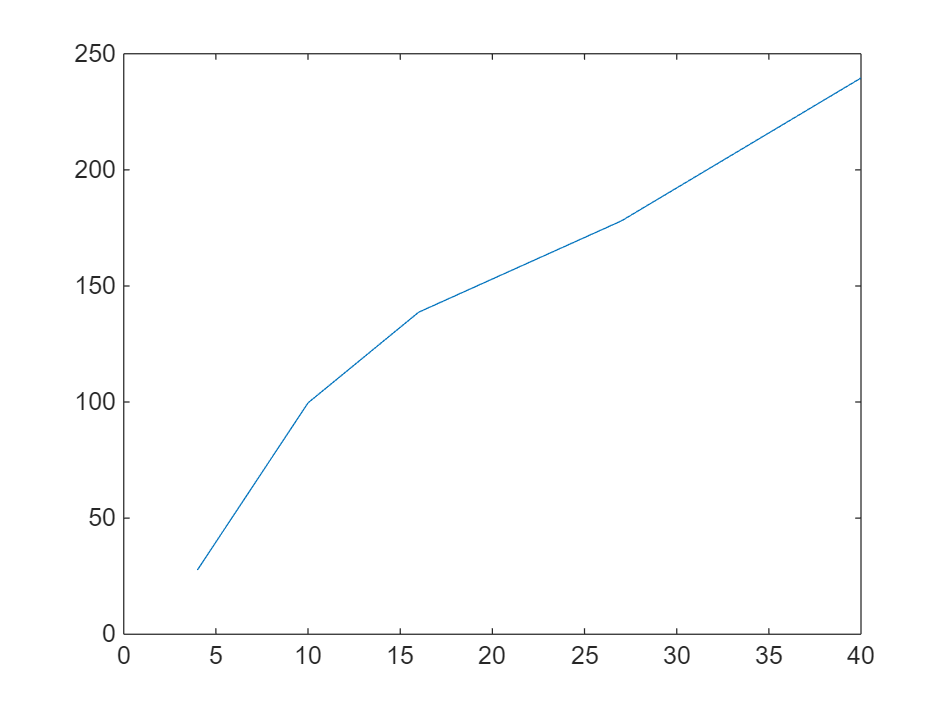

figure;
plot(data2plot(:,2),data2plot(:,4))

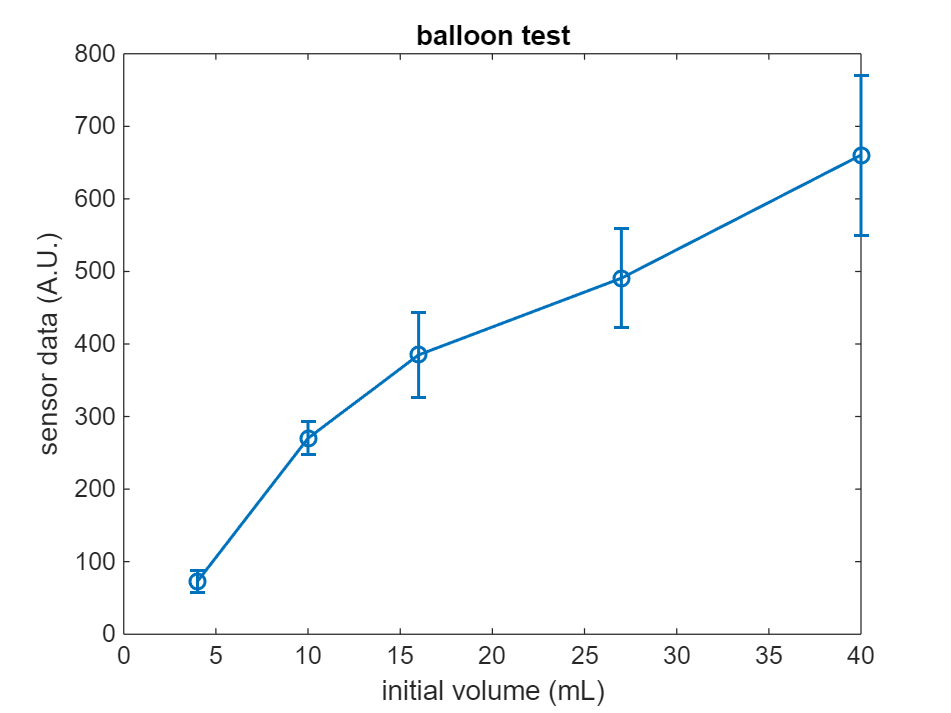


figure;
errorbar(data2plot(:,2),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('initial volume (mL)')
ylabel('sensor data (A.U.)')
title('balloon test')

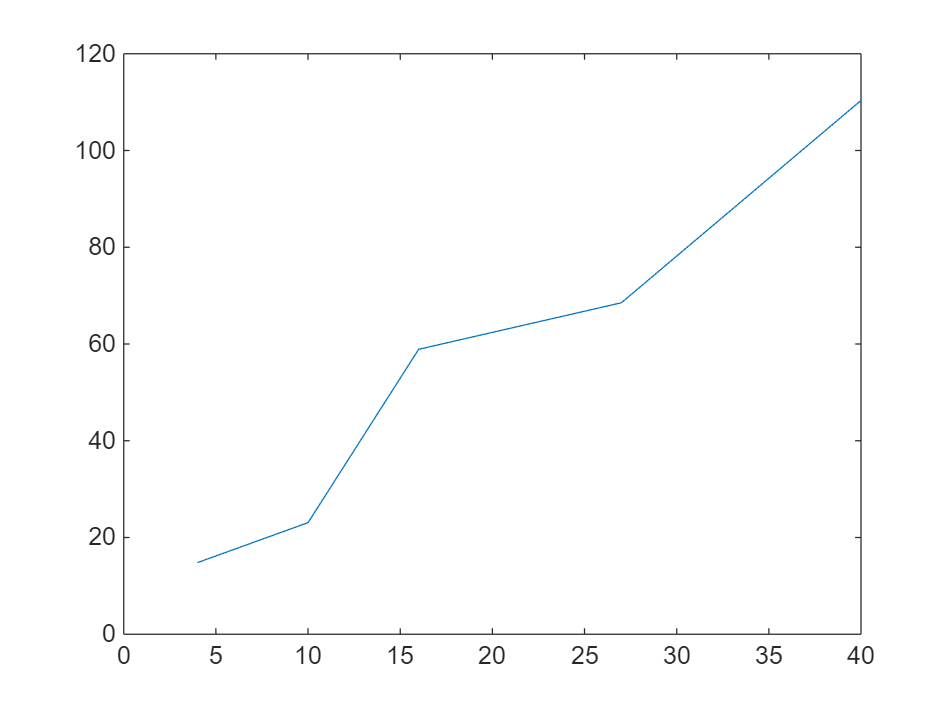



figure;
plot(data2plot(:,2),data2plot(:,6))

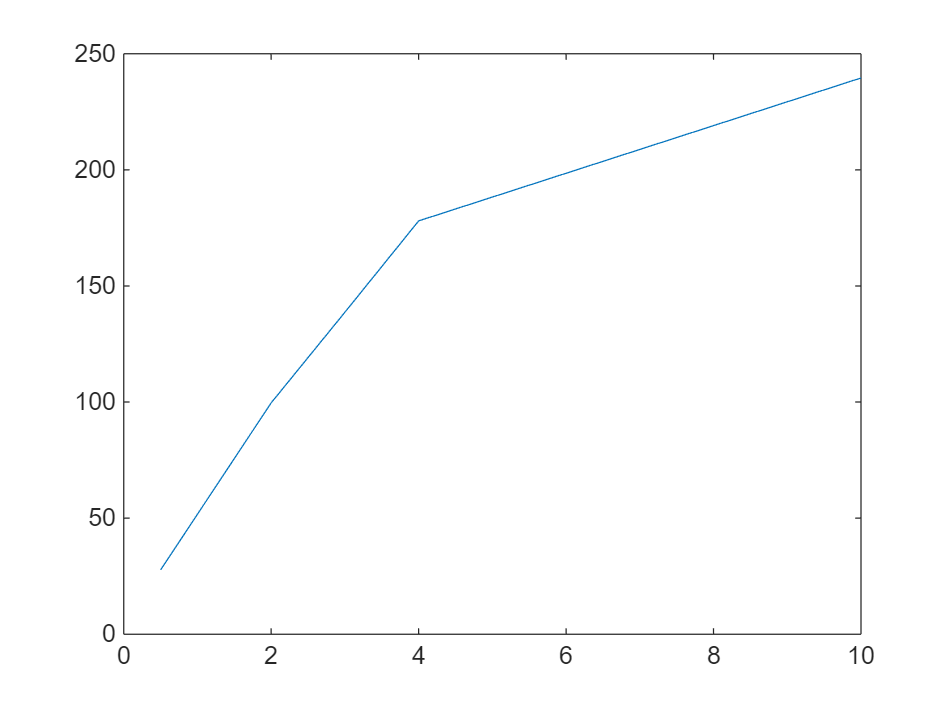

figure;
plot(data2plot(:,3),data2plot(:,4))

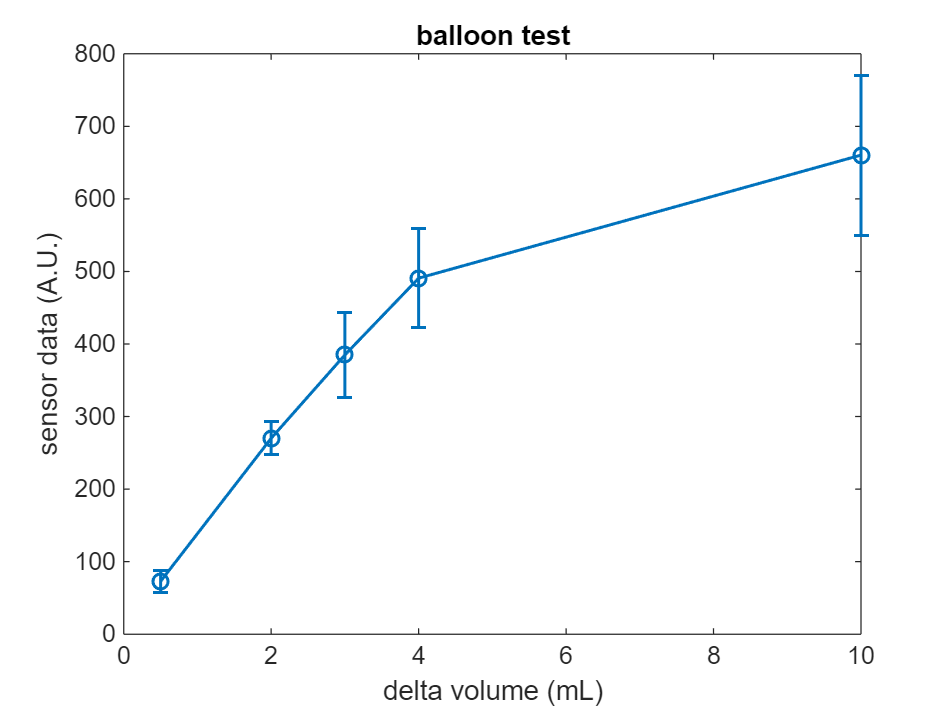


figure;
errorbar(data2plot(:,3),data2plot(:,5), data2plot(:,6), 'o-','LineWidth',1.2,'MarkerSize',6);
xlabel('delta volume (mL)')
ylabel('sensor data (A.U.)')
title('balloon test')

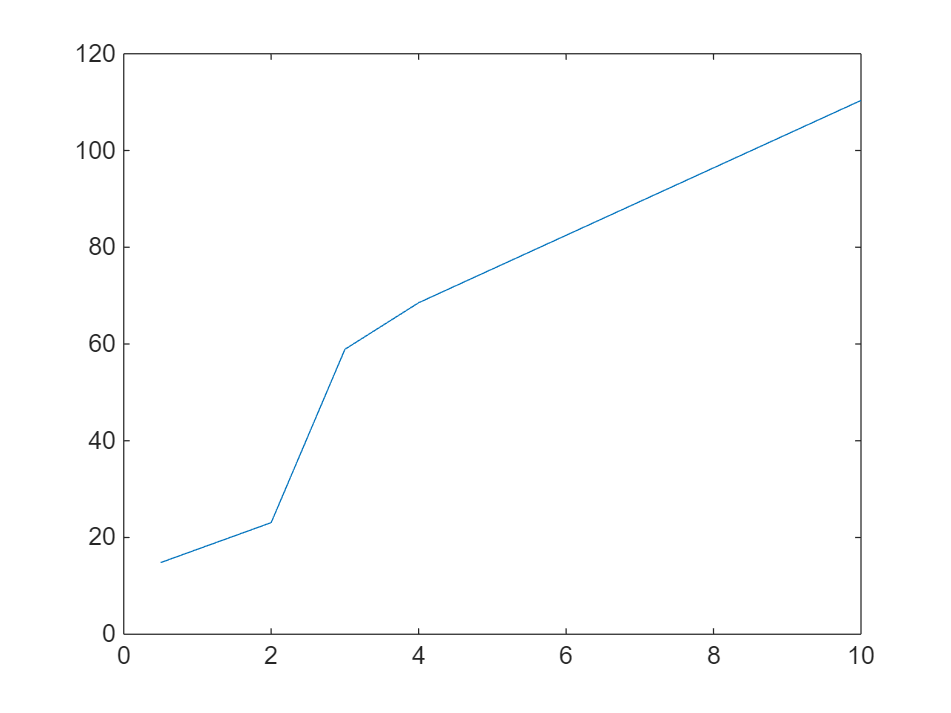



figure;
plot(data2plot(:,3),data2plot(:,6))

numGroups = numel(data2compare);
pairs    = nchoosek(1:numGroups,2);
numPairs = size(pairs,1);

p_raw  = nan(numPairs,1);

for k = 1:numPairs
    i = pairs(k,1);
    j = pairs(k,2);
    [~, p_raw(k)] = ttest2(data2compare{i}, data2compare{j}, 'Vartype','unequal');
end

p_bonf = min(p_raw * numPairs, 1);

results = table(pairs(:,1), pairs(:,2), p_raw, p_bonf, ...
    'VariableNames', {'Group1','Group2','p_raw','p_bonf'});

disp(results);

    Group1    Group2      p_raw         p_bonf  
    ______    ______    __________    __________

      1         2        3.701e-26     3.701e-25
      1         3       1.4504e-16    1.4504e-15
      1         4       1.5212e-17    1.5212e-16
      1         5       6.6292e-16    6.6292e-15
      2         3       1.9562e-08    1.9562e-07
      2         4       1.3767e-12    1.3767e-11
      2         5       7.7581e-13    7.7581e-12
      3         4       6.7512e-06    6.7512e-05
      3         5       9.3369e-11    9.3369e-10
      4         5       1.7725e-06    1.7725e-05



mdl_wk = fitlm(data2plot(:,1),data2plot(:,5))

mdl_wk = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -498.04      22.866    -21.781    0.00021182
    x1              29.128     0.74329     39.189    3.6558e-05


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 11.3
R-squared: 0.998,  Adjusted R-Squared: 0.997
F-statistic vs. constant model: 1.54e+03, p-value = 3.66e-05


mdl_vini = fitlm(data2plot(:,2),data2plot(:,5))

mdl_vini = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat      pValue  
                   ________    ______    ______    _________

    (Intercept)      83.02     48.345    1.7172      0.18444
    x1              15.092     2.0801    7.2557    0.0054015


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 59.5
R-squared: 0.946,  Adjusted R-Squared: 0.928
F-statistic vs. constant model: 52.6, p-value = 0.0054


mdl_vdelta = fitlm(data2plot(:,3),data2plot(:,5))

mdl_vdelta = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)     158.08     71.336     2.216     0.11346
    x1              55.827     14.031    3.9789    0.028398


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 102
R-squared: 0.841,  Adjusted R-Squared: 0.788
F-statistic vs. constant model: 15.8, p-value = 0.0284


overallWkData = [];
for i = 1:length(p2pdata)
    overallWkData = [overallWkData;p2pdata{i}];
end



mdl_wk_all = fitlm(log(overallWkData(:,1)),overallWkData(:,4))

mdl_wk_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -2450.3      93.83    -26.115    6.1942e-46
    x1              837.61     27.741     30.194    1.9609e-51


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 65.6
R-squared: 0.903,  Adjusted R-Squared: 0.902
F-statistic vs. constant model: 912, p-value = 1.96e-51

mdl_vini_all = fitlm(log(overallWkData(:,2)),overallWkData(:,4))

mdl_vini_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)    -284.15      24.09    -11.795    1.6346e-20
    x1              245.41     8.5838      28.59    2.4032e-49


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 68.9
R-squared: 0.893,  Adjusted R-Squared: 0.892
F-statistic vs. constant model: 817, p-value = 2.4e-49

mdl_vdelta_all = fitlm(log(overallWkData(:,3)),overallWkData(:,4))

mdl_vdelta_all = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     184.34     9.9888    18.455    1.1719e-33
    x1              199.97     7.2884    27.437     8.719e-48


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 71.5
R-squared: 0.885,  Adjusted R-Squared: 0.884
F-statistic vs. constant model: 753, p-value = 8.72e-48

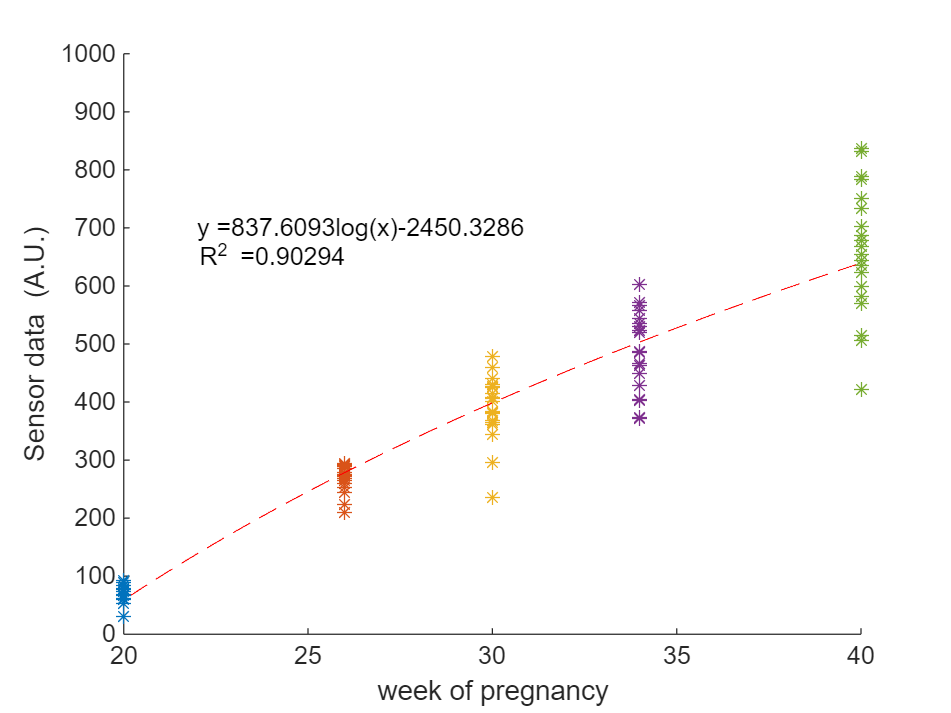


x = 0:0.01:50;
y_wk = log(x).*mdl_wk_all.Coefficients{"x1","Estimate"} + mdl_wk_all.Coefficients{'(Intercept)',"Estimate"};
y_vini = log(x).*mdl_vini_all.Coefficients{"x1","Estimate"} + mdl_vini_all.Coefficients{'(Intercept)',"Estimate"};
y_vdelta = log(x).*mdl_vdelta_all.Coefficients{"x1","Estimate"} + mdl_vdelta_all.Coefficients{'(Intercept)',"Estimate"};


equation_wk = strcat('y = ',num2str(mdl_wk_all.Coefficients{"x1","Estimate"}),'log(x) ',num2str(mdl_wk_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_wk = strcat('R^2 = ',num2str(mdl_wk_all.Rsquared.Ordinary));

equation_vini = strcat('y = ',num2str(mdl_vini_all.Coefficients{"x1","Estimate"}),'log(x) + ',num2str(mdl_vini_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_vini = strcat('R^2 = ',num2str(mdl_vini_all.Rsquared.Ordinary));

equation_vdelta = strcat('y = ',num2str(mdl_vdelta_all.Coefficients{"x1","Estimate"}),'log(x) + ',num2str(mdl_vdelta_all.Coefficients{'(Intercept)',"Estimate"}));
R_sq_vdelta = strcat('R^2 = ',num2str(mdl_vdelta_all.Rsquared.Ordinary));

figure;

hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,1),p2pdata{i}(:,4),'*')
end
plot(x,y_wk,'r--')
text(22, 700, equation_wk);
text(22, 650, R_sq_wk);
hold off
xlabel('week of pregnancy')
ylabel('Sensor data  (A.U.)')
xlim([20 40])
ylim([0 1000])

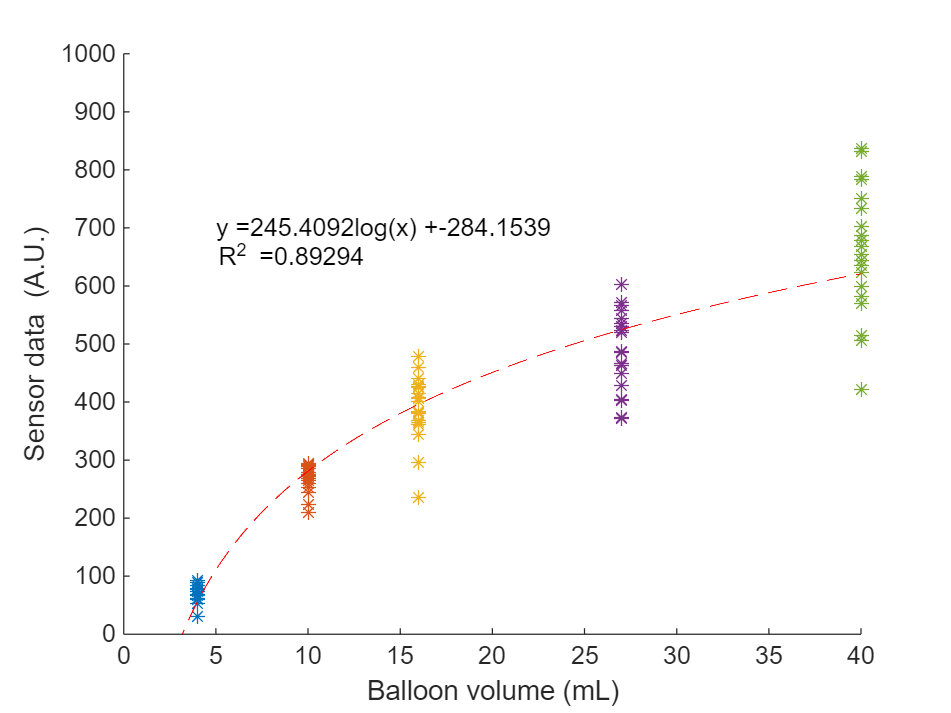


figure;
hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,2),p2pdata{i}(:,4),'*')
end
plot(x,y_vini,'r--')
text(5, 700, equation_vini);
text(5, 650, R_sq_vini);
hold off
xlabel('Balloon volume (mL)')
ylabel('Sensor data  (A.U.)')
xlim([0 40])
ylim([0 1000])

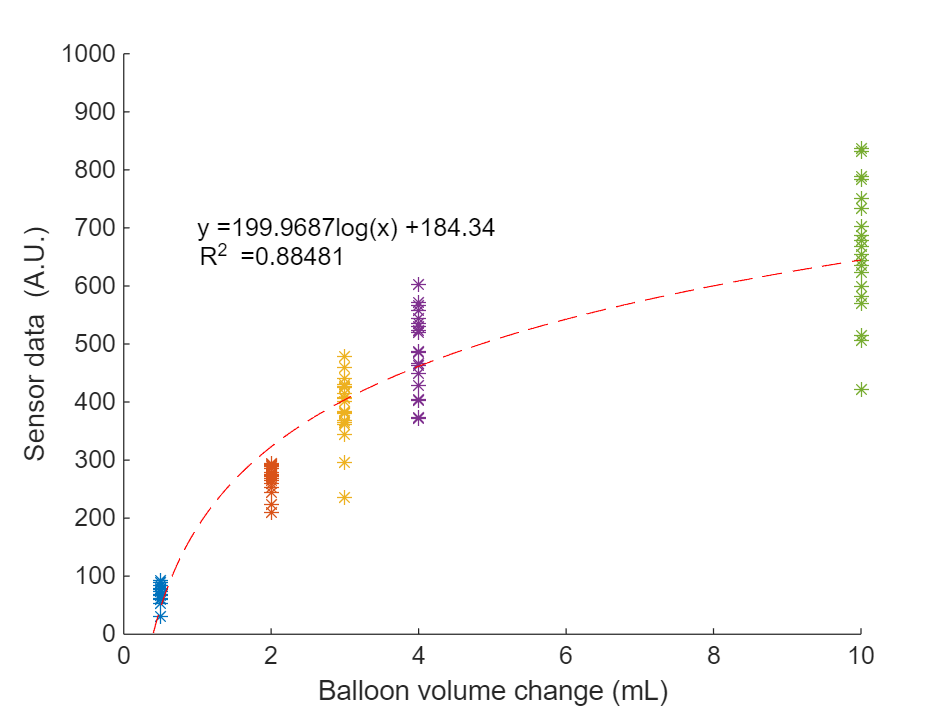


figure;
hold on
for i = 1:length(p2pdata)
    plot(p2pdata{i}(:,3),p2pdata{i}(:,4),'*')
end
plot(x,y_vdelta,'r--')
text(1, 700, equation_vdelta);
text(1, 650, R_sq_vdelta);
hold off
xlabel('Balloon volume change (mL)')
ylabel('Sensor data  (A.U.)')
xlim([0 10])
ylim([0 1000])

corr_wk = corr(overallWkData(:,1),overallWkData(:,4))

corr_wk = 0.9518

corr_vini = corr(overallWkData(:,2),overallWkData(:,4))

corr_vini = 0.9267

corr_vdelta = corr(overallWkData(:,3),overallWkData(:,4))

corr_vdelta = 0.8736


wk_ideal = [];
vini_ideal = [];
vdelta_ideal = [];

wk_MAerror = 0;
vini_MAerror = 0;
vdelta_MAerror = 0;

wk_RMSerror = 0;
vini_RMSerror = 0;
vdelta_RMSerror = 0;

for i = 1:length(weeks)
    wk_ideal = y_wk(x==weeks(i));
    vini_ideal = y_vini(x==volume(i));
    vdelta_ideal = y_vdelta(x==delta_v(i));
    wk_MAerror = wk_MAerror + sum(abs(p2pdata{i}(:,4)-wk_ideal));
    vini_MAerror = vini_MAerror + sum(abs(p2pdata{i}(:,4)-vini_ideal));
    vdelta_MAerror = vdelta_MAerror + sum(abs(p2pdata{i}(:,4)-vdelta_ideal));

    wk_RMSerror = wk_RMSerror + sum((p2pdata{i}(:,4)-wk_ideal).^2);
    vini_RMSerror = vini_RMSerror + sum((p2pdata{i}(:,4)-vini_ideal).^2);
    vdelta_RMSerror = vdelta_RMSerror + sum((p2pdata{i}(:,4)-vdelta_ideal).^2);
end

wk_MAE = wk_MAerror / length(overallWkData(:,4))

wk_MAE = 44.6255

vini_MAE = vini_MAerror / length(overallWkData(:,4))

vini_MAE = 46.3990

vdelta_MAE = vdelta_MAerror / length(overallWkData(:,4))

vdelta_MAE = 55.0404


wk_RMSE = sqrt(wk_RMSerror / length(overallWkData(:,4)))

wk_RMSE = 64.9441

vini_RMSE = sqrt(vini_RMSerror / length(overallWkData(:,4)))

vini_RMSE = 68.2064

vdelta_RMSE = sqrt(vdelta_RMSerror / length(overallWkData(:,4)))

vdelta_RMSE = 70.7490


5.33

wk_MAE_perc = 0.0533

vini_MAE_perc = 0.0554

vdelta_MAE_perc = 0.0658

wk_RMSE_perc = 0.0776

vini_RMSE_perc = 0.0815

vdelta_RMSE_perc = 0.0845